# Assignment 1

clear
rng(10)
addpath('functions')


## Question 1.1

- A(q−1)=1−3.88098254q−1 −5.64726905q−2+3.6515443q−3−0.88525793q−4.

- B(q−1)=0.4453368−1.7110786q−1+2.49838163q−2−1.64272524q−3+0.41012833q−4B(q^{-1}) = 0.4453368 - 1.7110786 q^{-1} + 2.49838163 q^{-2} - 1.64272524 q^{-3} + 0.41012833 q^{-4}B(q−1)=0.4453368−1.7110786q−1+2.49838163q−2−1.64272524q−3+0.41012833q−4

s.A = [1, -3.88098254, 5.64726905, -3.6515443, 0.88525793];
s.B = [0.4453368,-1.71110786,2.49838163, -1.64272524, 0.41012833];
% q^-1



## Question 1.2

- ϕt�=[yt−1�,yt−2�,yt−3�,yt−4�,ut�,ut−1�,ut−2�,ut−3�,ut−4�]T.

- θ=[3.88098254,5.64726905,−3.6515443,0.88525793,0.4453368,−1.7110786,2.49838163,−1.64272524,0.41012833]T\theta = [3.88098254, 5.64726905, -3.6515443, 0.88525793, 0.4453368, -1.7110786, 2.49838163, -1.64272524, 0.41012833]^Tθ=[3.88098254,5.64726905,−3.6515443,0.88525793,0.4453368,−1.7110786,2.49838163,−1.64272524,0.41012833]T

syms y_1 y_2 y_3 y_4 u_0 u_1 u_2 u_3 u_4 
phi =  [y_1 y_2 y_3 y_4 u_0 u_1 u_2 u_3 u_4]';
% q^-1
theta = ([3.88098254,5.64726905,-3.6515443,0.88525793,0.4453368,-1.7110786,2.49838163,-1.64272524,0.41012833]');
vpa(phi'*theta)

$$ans = 0.44533679999999997711768173758173\,u_{0}-1.7110786000000000051102233555866\,u_{1}+2.4983816299999999088754520926159\,u_{2}-1.6427252400000000864821458890219\,u_{3}+0.41012832999999998540019419124292\,u_{4}+3.8809825400000002026956735790009\,y_{1}+5.6472690500000002344904714846052\,y_{2}-3.6515442999999998541227341775084\,y_{3}+0.88525792999999997068272250544396\,y_{4}$$

## Question 1.3

Stable with no stochastic term:

eigs = roots(s.A)

eigs =    0.9902 + 0.0000i
   0.9947 + 0.0000i
   0.9480 + 0.0005i
   0.9480 - 0.0005i


abs(eigs)

ans =     0.9902
    0.9947
    0.9480
    0.9480


## Question 1.4

data = readmatrix('Assignment1_ObservationsAndInputs.txt')';


% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
s.u_data = data(:,2);
%% System Parameters
s.N = 1000;  % Number of time steps
s.sigma_e = 10^-10;  % Standard deviation of process noise
% s.sigma_e = 0.00001;
s.k = 1;  % Input delay
s.alpha = 0.01; % Gain for P ctrl
n_max = max([length(s.A),length(s.B)]);
s.u_init = zeros(n_max,1);
s.y_init = zeros(n_max,1);
s.ref = data(1:s.N,1);

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
% Stochastic(Stochastic) (True [1],  False [2])
% Control type (ctrl) (Pctrl [1], MV [2], MV0 [3], s.u_data [4], Off [5])
SP = 1;
Stochastic = 1;
ctrl = 4;
s = run_case(s, SP, Stochastic, ctrl);






y_obs = data(:,1);  % First row: actual observed outputs
u_data = data(:,2);      % Second row: input values
k = s.k;
N = length(y_obs);  % Total number of observations
m = 10;  % Prediction horizon (can be adjusted)

% Initialize predicted values
y_pred = zeros(1, N);  % Store predictions

[G,S] = diophantine(s.A,1,m)

G =     1.0000    3.8810    9.4148   18.2731   31.0362   48.2007   70.1867   97.3447  129.9619  168.2681


S =   212.4405 -561.8684  499.3884 -148.9606


R = conv(s.B,G)

R =     0.4453    0.0172    0.0503    0.0815    0.1107    0.1382    0.1640    0.1883    0.2110    0.2323  -94.3553  246.8299 -223.1171   69.0115



% Simulate predictions iteratively
for t = m+numel(s.B)+max([numel(S),numel(s.B),numel(R)])+k:N-numel(R) - k-m
    % Predict y_{t+m} using the ARX equation
    % y_pred(t+m) = R* u_data(t+m-k+(0:numel(R)-1)) + S * s.y(t-(0:numel(S)-1));
    Rterm(t) = R* u_data(t+m-numel(s.B)-k-(0:numel(R)-1));
    Sterm(t) = S * y_obs(t-(0:numel(S)-1));
    y_pred(t+m) =  Rterm(t) + Sterm(t);
end

% Compute Mean Absolute Error (MAE)
MAE = mean(abs(y_pred(m+1:end) - y_obs(m+1:end)'));

% Display result
fprintf('Mean Absolute Error (MAE): %.5f\n', MAE);

Mean Absolute Error (MAE): 107.41150


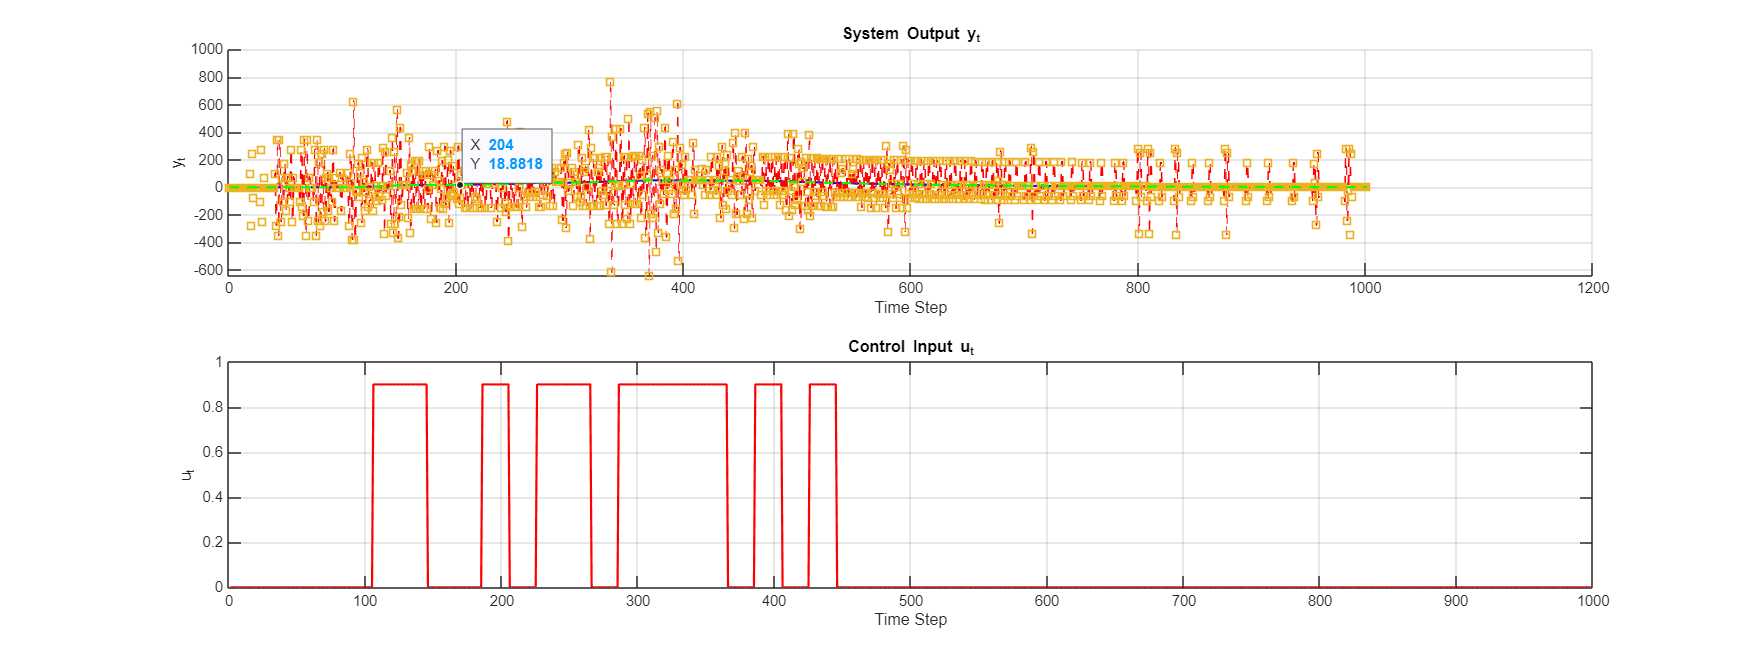

sys = idpoly(s.A,s.B,'nk',1,'InputDelay', max([length(s.A), length(s.B)]));
data_arx = sim(sys,u_data);
figure
yp = predict(sys,[y_obs,u_data],m);


%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(s.y(1:end), 'b', 'LineWidth', 1.5);
% plot(data(1:end-1,1), 'r', 'LineWidth', 1.5);
plot(y_pred(1:end-1)', 'r--', 'LineWidth', 1.5);
plot(yp(1:end)', 's', 'LineWidth', 1.5);
plot(data_arx(1:end), 'g--', 'LineWidth', 1.5);
hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(s.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;

## Question 1.5

[G,S] = diophantine(s.A,1,100)

G = 1.0e+04 *

    0.0001    0.0004    0.0009    0.0018    0.0031    0.0048    0.0070    0.0097    0.0130    0.0168    0.0212    0.0263    0.0319    0.0381    0.0450    0.0524    0.0605    0.0692    0.0785    0.0883    0.0987    0.1097    0.1212    0.1333    0.1458    0.1589    0.1724    0.1863    0.2007    0.2155    0.2307    0.2463    0.2622    0.2784    0.2950    0.3118    0.3290    0.3463    0.3639    0.3818    0.3998    0.4180    0.4363    0.4548    0.4735    0.4922    0.5111    0.5300    0.5490    0.5680


S = 1.0e+04 *

    1.4028   -4.0299    3.8585   -1.2314


R = conv(s.B,G)

R = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


## Question 1.6

## Question 1.7

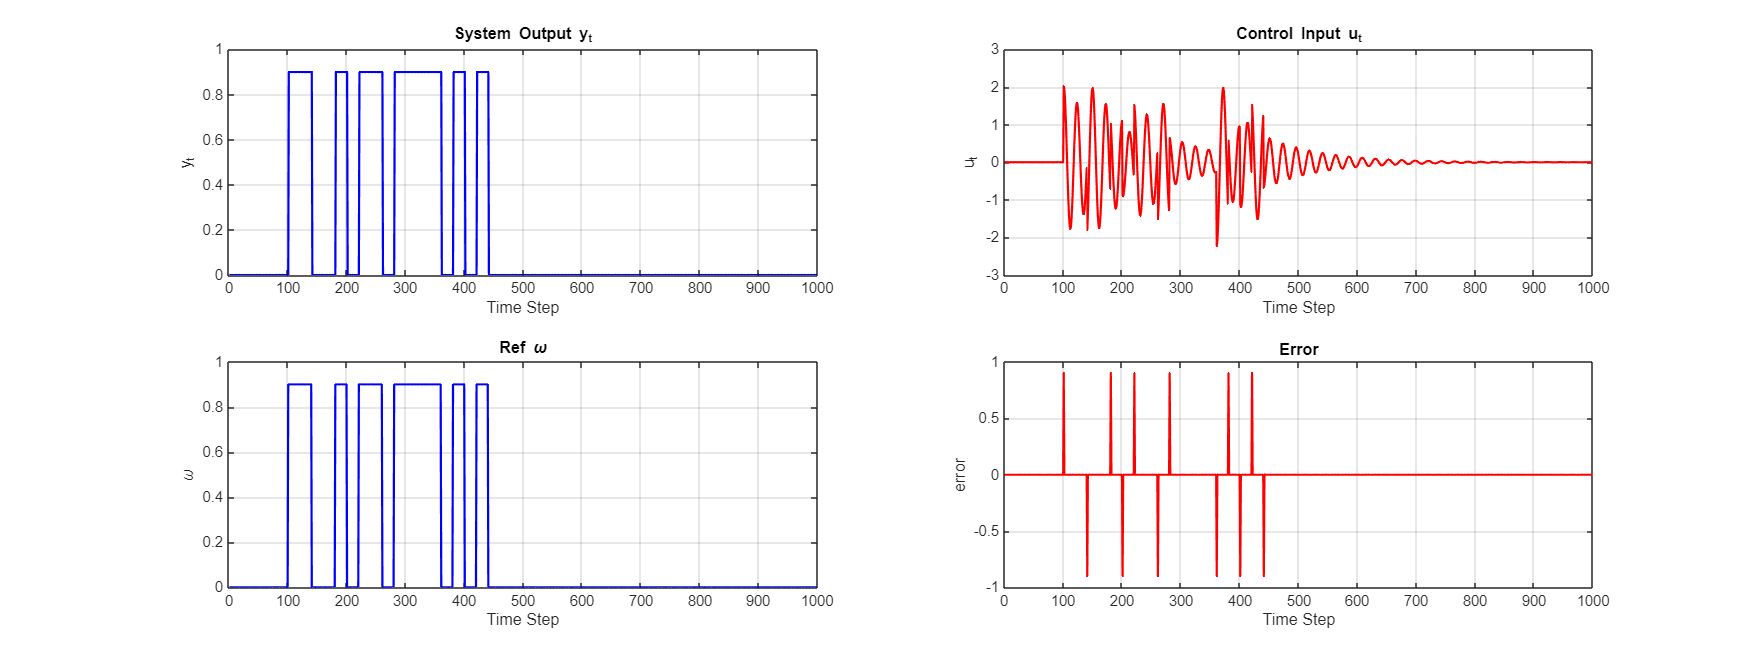

s.u_data = readmatrix('Assignment1_ObservationsAndInputs.txt')';
%% System Parameters
s.N = 1000;  % Number of time steps
s.sigma_e = 10^-10;  % Standard deviation of process noise
s.k = 1;  % Input delay
s.alpha = 0.5; % Gain for P ctrl
n_max = max([length(s.A),length(s.B)]);
s.u_init = zeros(n_max,1);
s.y_init = zeros(n_max,1);
s.ref = s.u_data(1:s.N,2);

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
% Stochastic(Stochastic) (True [1],  False [2])
% Control type (ctrl) (Pctrl [1], MV [2], MV0 [3], u_data(:,2) [4], Off [5])
SP = 4;
Stochastic = 1;
ctrl = 3;
s = run_case(s, SP, Stochastic, ctrl);

%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];

%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,2,1);
plot(s.y, 'b', 'LineWidth', 1.5);
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,2,2);
plot(s.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;
subplot(2,2,3)
plot(s.omega, 'b', 'LineWidth', 1.5);
title('Ref \omega');
% ylim([-max(omega)*1.2,max(omega)*1.2])
xlabel('Time Step');
ylabel('\omega');
grid on;
subplot(2,2,4)
plot(s.omega-s.y, 'r', 'LineWidth', 1.5);
title('Error');
xlabel('Time Step');
ylabel('error');
grid on;